# Analysis of Correlation Dimension

We have the (approximation to the) correlation integral of the final timestep for five independent runs of each concentration.  We need to read in each data file and then

nmols = [42 126 200 252 378];
nruns = 5;
fbase = '/home/rachael/cluster/data/mansbac2/coarsegraining/MD/DFAG/';
fend = '/4_md/corrdimdata/test_cdim_400_snap.dat';
cmat = [];
for i = 1:length(nmols)
   for j = 1:nruns
      folder = [fbase int2str(nmols(i)) 'mols_run' int2str(j) fend];
      c = readlinebyline(folder,'%f',[]);
      if isempty(cmat)
          cmat = zeros(size(c,1),length(nmols)*nruns);
          eps = c(:,1);
      end
      cmat(:,(i-1)*nruns+j) = c(:,2);
   end
end

(i) Make a plot for each concentration and for all concentrations

(ii) identify approximate linear regions

(iii) extract slopes of those regions

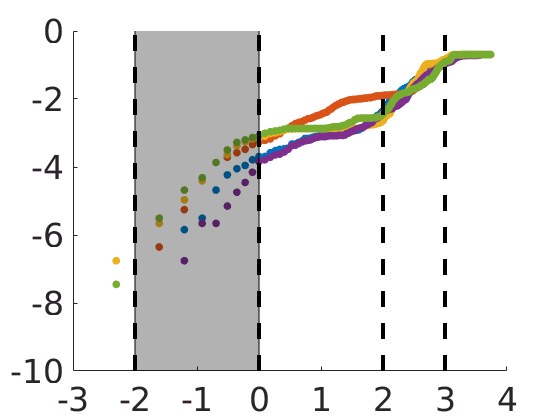

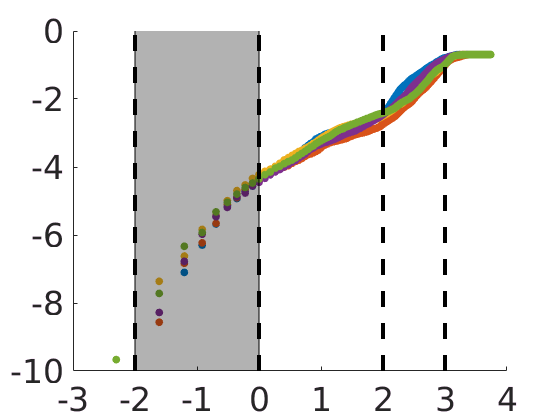

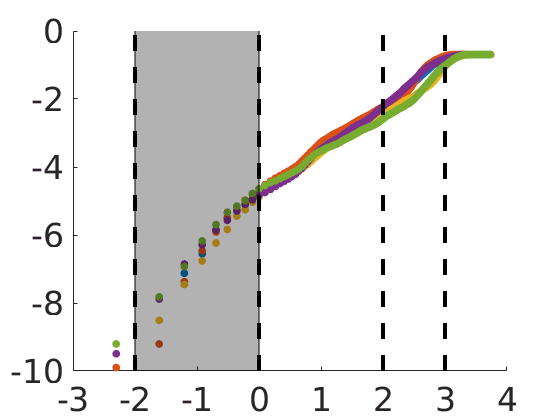

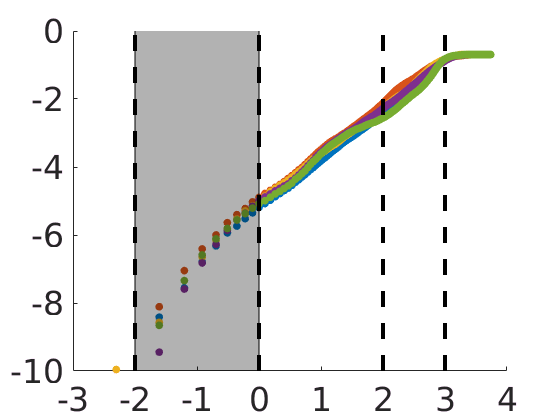

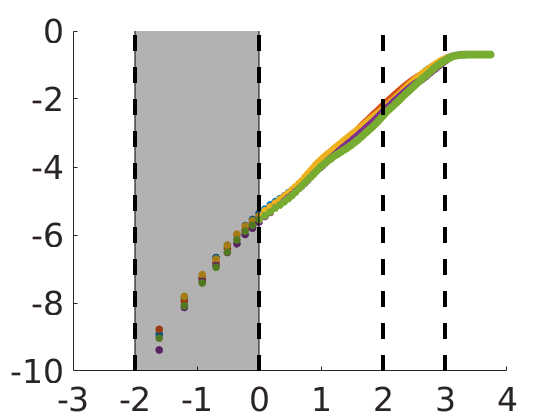

cd1 = zeros(nruns,length(nmols));
cd2 = zeros(nruns,length(nmols));
cdm = zeros(nruns,length(nmols));
%%%region definition, taken from visualizations already shown
%mis1 = [-0.7 -0.7 -0.7 -0.5 -0.7];
%mis1 = [-0.5 -0.5 -0.5 -0.5 -0.5];
mis1 = [-2 -2 -2 -2 -2];
%mas1 = [0.4 0.47 0.47 0.33 0.26];
%mas1 = [0.4 0.4 0.4 0.4 0.4];
mas1 = [0 0 0 0 0];
%mis2 = [2.4 2.2 2.4 2 1];
%mis2 = [2.4 2.4 2.4 2.4 2.4];
mis2 = [2 2 2 2 2];
%mas2 = [3 2.8 3 3 3];
mas2 = [3 3 3 3 3];
%%%%
for i = 1:length(nmols)
   figure()
   hold on
   for j = 1:nruns
          plot(log(eps),log(cmat(:,(i-1)*nruns+j)),'.','linewidth',2,'markersize',20)   
   end
   mi1 = mis1(i);
   ma1 = mas1(i);
   idx_lo1 = find(eps>exp(mi1),1,'first');
   idx_hi1 = find(eps>exp(ma1),1,'first');
   mi2 = mis2(i);
   ma2 = mas2(i);
   idx_lo2 = find(eps>exp(mi2),1,'first');
   idx_hi2 = find(eps>exp(ma2),1,'first');
   ylim([-10 0])
   xlim([-3 4])
   plot([mi1 mi1],[-20 20],'k--','linewidth',3)
   plot([mi2 mi2],[-20 20],'k--','linewidth',3)
   %patch([mi1 ma1 ma1 mi1],[-20 -20 20 20],'k','facealpha',0.3)
   plot([ma1 ma1],[-20 20],'k--','linewidth',3)
   plot([ma2 ma2],[-20 20],'k--','linewidth',3)
   %patch([mi2 ma2 ma2 mi2],[-20 -20 20 20],'k','facealpha',0.3)
   set(gca,'fontsize',25)
   set(gca,'Xtick',-3:4)
   set(gca,'Ytick',-10:2:0)
   savefig(['/home/rachael/coarsegraining/Data/corrdim' int2str(nmols(i))])
   saveas(gcf,['/home/rachael/coarsegraining/Data/corrdim' int2str(nmols(i))],'png')
   for j = 1:nruns
       le = log(eps(idx_lo1:idx_hi1));
       lc = log(cmat(idx_lo1:idx_hi1,(i-1)*nruns+j));
       lef = le(~isinf(lc));
       lcf = lc(~isinf(lc));
   b1 = fit(lef,lcf,'poly1');
   b2 = fit(log(eps(idx_lo2:idx_hi2)),log(cmat(idx_lo2:idx_hi2,(i-1)*nruns+j)),'poly1');
   bm = fit(log(eps(idx_hi1:idx_lo2)),log(cmat(idx_hi1:idx_lo2,(i-1)*nruns+j)),'poly1');
   cd1(j,i) = b1.p1;
   cd2(j,i) = b2.p1;
   cdm(j,i) = bm.p1;
   end
   
   %title([int2str(nmols(i)) ' mols']);
end

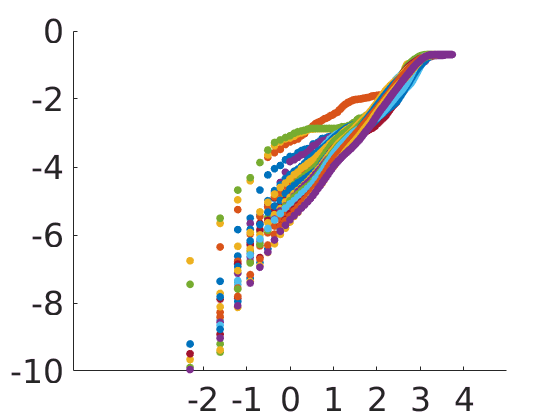

figure()
hold on
for i = 1:size(cmat,2)
 
   plot(log(eps),log(cmat(:,i)),'.','linewidth',2,'markersize',20) 
   set(gca,'fontsize',25)
   ylim([-10 0])
   set(gca,'Xtick',-2:1:4)
   set(gca,'Ytick',-10:2:0)
   %title('all concentrations')
end
savefig('/home/rachael/coarsegraining/Data/corrdim')
saveas(gcf,'/home/rachael/coarsegraining/Data/corrdim','png')

(iv) take mean and stdev (either of all or of each concentration)

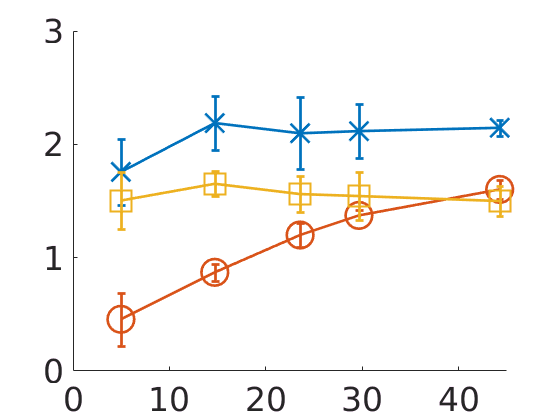

mcd1 = mean(cd1);
mcd2 = mean(cd2);
mcdm = mean(cdm);
scd1 = std(cd1);
scd2 = std(cd2);
scdm = std(cdm);
figure()
hold on
concs = [4.9671,14.7,23.545,29.646,44.24]; %mM
errorbar(concs,mcd1,scd1,'x-','markersize',20,'linewidth',2);
errorbar(concs,mcdm,scdm,'o-','markersize',20,'linewidth',2);
errorbar(concs,mcd2,scd2,'s-','markersize',20,'linewidth',2);

set(gca,'fontsize',25)
set(gca,'Xtick',0:10:40)
ylim([0 3])
xlim([0 45])
%legend('region 1','region 2','region 3','location','southeast')
savefig('/home/rachael/coarsegraining/Data/mcorrdim')
saveas(gcf,'/home/rachael/coarsegraining/Data/mcorrdim','png')

fprintf('Mean of region 1: %f +/- %f\n',mean(reshape(cd1,25,1)),std(reshape(cd1,25,1)));

Mean of region 1: 2.060891 +/- 0.275755


fprintf('Mean of region 2: %f +/- %f\n',mean(reshape(cd2,25,1)),std(reshape(cd2,25,1)));

Mean of region 2: 1.552077 +/- 0.175051
